## Weak Scaling Efficiency

Starting with a problem size (N) of 2^22 and 1 processor, the execution time was recorded and both the problem size and number of processors were increased by a factor of 2x. In an ideal situation, the execution time should be identical on each repetition as the processors should be handling the same amount of information each time. Of course, this is not possible because communication must occur, and this is especially true as the number of processors increases. This can be seen below.

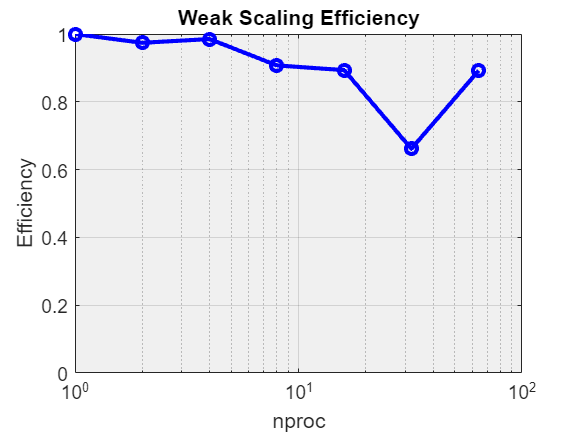

%Reading data
speedData=readmatrix('weakScaling1.csv');
nproc=speedData(:,1);
time=speedData(:,2);

%Plotting
E=time(1)./time;
semilogx(nproc,speedup,'bo-','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Efficiency','FontSize',14);
ylim([0 1]);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Weak Scaling Efficiency');

If processors could talk to each other and instantaneously perform calculations with no time in between, every program would reach near maximum efficiency (aside from hardware limitations). However, computers can only do 1 thing at a time. This communication process is not an issue until the node limit is reached. As mentioned in the strong scaling analysis, Boise State's R2 supercomputer has 28 processors per node. This means that once more than 28 processors are requested for a job, more than 1 node has to be used. This communication between nodes slows execution time tremendously as we see the massive dip in execution time between 16 and 32 processors. Execution time dropped from it's consistent .1 second range to over .14 seconds! When 64 processors are used, the entire computational power of 2 nodes is used with some left over on a 3rd node. This means there is a lot less wasteful cross-node communication. It is important to be mindful of the specifications of your machine when running parallel programs to maximize efficiency.